%Q1.1 and 1.2
t=0:1/120:2;
y=sin(2*pi*15*t)

y =          0    0.7071    1.0000    0.7071    0.0000   -0.7071   -1.0000   -0.7071   -0.0000    0.7071    1.0000    0.7071    0.0000   -0.7071   -1.0000   -0.7071   -0.0000    0.7071    1.0000    0.7071    0.0000   -0.7071   -1.0000   -0.7071   -0.0000    0.7071    1.0000    0.7071    0.0000   -0.7071   -1.0000   -0.7071   -0.0000    0.7071    1.0000    0.7071    0.0000   -0.7071   -1.0000   -0.7071   -0.0000    0.7071    1.0000    0.7071    0.0000   -0.7071   -1.0000   -0.7071   -0.0000    0.7071


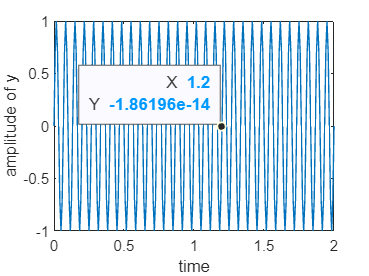

plot(t,y)

xlabel("time")
ylabel("amplitude of y")
ax = gca;
chart = ax.Children(1);
datatip(chart,1.2,-1.862e-14);

figure;
w=2*pi*(15/120);
N=120;
n=0:N-1;
y=sin(w.*n);
freq=(0:N-1)/120;
z=fft(y);
X1=plot(freq*120,abs(z)/N);
hold on
N=130;
n=0:N-1;
y=sin(w.*n);
freq=(0:N-1)/130;
z1=fft(y)

z1 =    0.7071 + 0.0000i   0.7119 - 0.0828i   0.7267 - 0.1674i   0.7520 - 0.2558i   0.7891 - 0.3503i   0.8401 - 0.4535i   0.9078 - 0.5693i   0.9968 - 0.7026i   1.1139 - 0.8607i   1.2698 - 1.0547i   1.4824 - 1.3028i   1.7830 - 1.6368i   2.2330 - 2.1181i   2.9693 - 2.8838i   4.3721 - 4.3145i   8.0391 - 8.0080i  41.1328 -41.1267i -14.0508 +14.0330i  -6.1782 + 6.1376i  -4.0375 + 3.9751i  -3.0428 + 2.9595i  -2.4700 + 2.3666i  -2.0989 + 1.9762i  -1.8396 + 1.6983i  -1.6489 + 1.4895i  -1.5030 + 1.3263i  -1.3881 + 1.1945i  -1.2956 + 1.0856i  -1.2196 + 0.9937i  -1.1562 + 0.9148i  -1.1027 + 0.8462i  -1.0571 + 0.7857i  -1.0177 + 0.7319i  -0.9835 + 0.6835i  -0.9535 + 0.6397i  -0.9272 + 0.5997i  -0.9038 + 0.5630i  -0.8831 + 0.5290i  -0.8646 + 0.4975i  -0.8479 + 0.4680i  -0.8330 + 0.4403i  -0.8195 + 0.4143i  -0.8074 + 0.3896i  -0.7963 + 0.3663i  -0.7863 + 0.3440i  -0.7773 + 0.3227i  -0.7690 + 0.3023i  -0.7615 + 0.2827i  -0.7547 + 0.2638i  -0.7485 + 0.2455i


X2=plot(freq*120,abs(z1)/N)

X2 =   Line with properties:

              Color: [0.8500 0.3250 0.0980]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 0.9231 1.8462 2.7692 3.6923 4.6154 5.5385 6.4615 7.3846 8.3077 9.2308 10.1538 11.0769 12 12.9231 13.8462 14.7692 15.6923 16.6154 17.5385 18.4615 19.3846 20.3077 21.2308 22.1538 23.0769 24 24.9231 25.8462 26.7692 27.6923 … ]
              YData: [0.0054 0.0055 0.0057 0.0061 0.0066 0.0073 0.0082 0.0094 0.0108 0.0127 0.0152 0.0186 0.0237 0.0318 0.0472 0.0873 0.4474 0.1528 0.0670 0.0436 0.0327 0.0263 0.0222 0.0193 0.0171 0.0154 0.0141 0.0130 0.0121 0.0113 0.0107 0.0101 … ]

  Show all prope

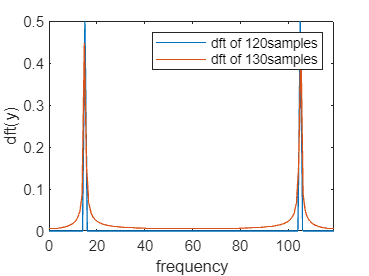

legend([X1 X2],'dft of 120samples','dft of 130samples')
hold off
%Q3
xlabel("frequency")
ylabel("dft(y)")

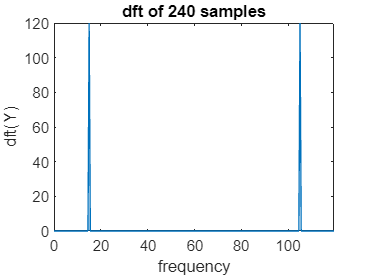

N=240;
n=0:N-1;
y=sin(w.*n);
freq=(0:N-1)/240;
z=fft(y);
plot(freq*120,abs(z))

title("dft of 240 samples")
xlabel("frequency")
ylabel("dft(Y)")

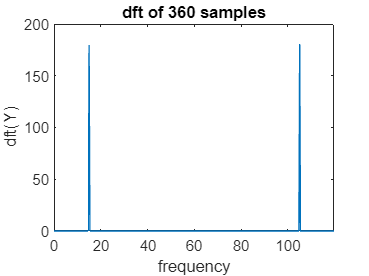

N=360;
n=0:N-1;
y=sin(w.*n);
freq=(0:N-1)/360;
z=fft(y);
plot(freq*120,abs(z))

title("dft of 360 samples")
xlabel("frequency")
ylabel("dft(Y)")

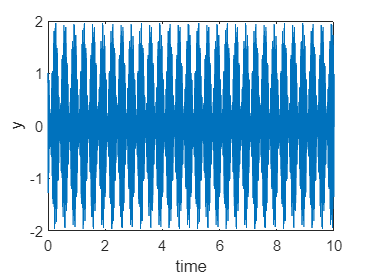

%Q2
t=0:1/200:10;
X=sin(120*pi*t)+cos(126*pi*t);

plot(t,X)

xlim([0.0 10.0])
ylim([-2.00 2.00])
xlabel("time")
ylabel("y")

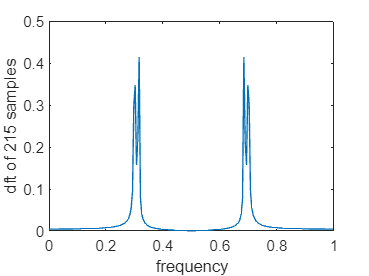

figure;
N=215;
n=0:N-1;
y=sin(120*pi/200.*n)+cos(126*pi/200.*n);
freq=(0:N-1)/215;
plot(freq,abs(fft(y)/N))
xlabel("frequency")
ylabel("dft of 215 samples")

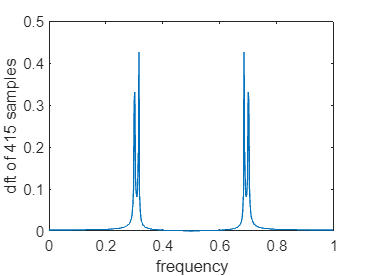

figure;
N=415;
n=0:N-1;
y=sin(120*pi/200.*n)+cos(126*pi/200.*n);
freq=(0:N-1)/415;
plot(freq,abs(fft(y)/N))
xlabel("frequency")
ylabel("dft of 415 samples")

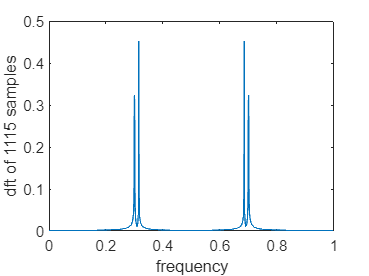

figure;
N=1115;
n=0:N-1;
y=sin(120*pi/200.*n)+cos(126*pi/200.*n);
freq=(0:N-1)/1115;
plot(freq,abs(fft(y)/N))
xlabel("frequency")
ylabel("dft of 1115 samples")

xlim([0.00 1.00])
ylim([0.000 0.500])

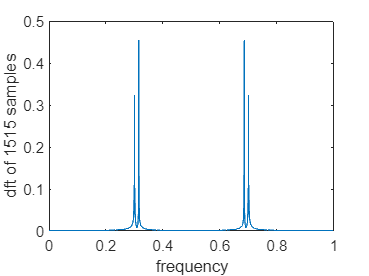

figure;
N=1515;
n=0:N-1;
y=sin(120*pi/200.*n)+cos(126*pi/200.*n);
freq=(0:N-1)/1515;
plot(freq,abs(fft(y)/N))
xlabel("frequency")
ylabel("dft of 1515 samples")

xlim([0.00 1.00])
ylim([0.000 0.500])

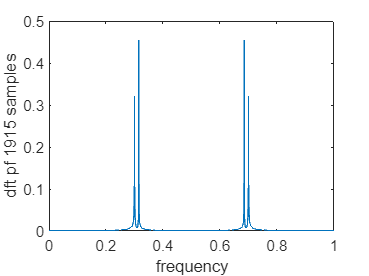

figure;
N=1915;
n=0:N-1;
y=sin(120*pi/200.*n)+cos(126*pi/200.*n);
freq=(0:N-1)/1915;
plot(freq,abs(fft(y)/N))
xlabel("frequency")
ylabel("dft pf 1915 samples")

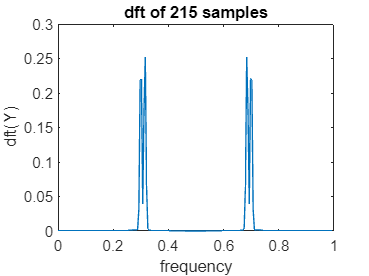

%Q3 for 215 samples
figure;
N=215;
n=0:N-1;
a=transpose(hamming(N));
y=(sin(120*pi/200.*n)+cos(126*pi/200.*n));
freq=(0:N-1)/N;
plot(freq,abs(fft(a.*y)/N))
title("dft of 215 samples")
xlabel("frequency")
ylabel("dft(Y)")

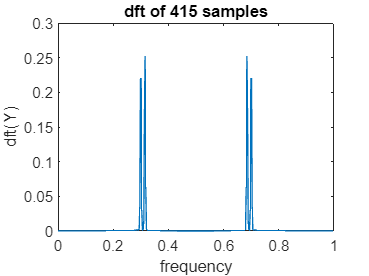

%Q3 for 415 samples
figure;
N=415;
n=0:N-1;
a=transpose(hamming(N));
y=(sin(120*pi/200.*n)+cos(126*pi/200.*n));
freq=(0:N-1)/N;
plot(freq,abs(fft(a.*y)/N))
title("dft of 415 samples")
xlabel("frequency")
ylabel("dft(Y)")

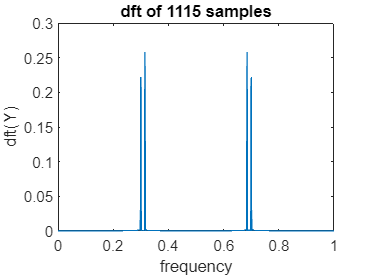

%Q3 for 1115 samples
figure;
N=1115;
n=0:N-1;
a=transpose(hamming(N));
y=(sin(120*pi/200.*n)+cos(126*pi/200.*n));
freq=(0:N-1)/N;
plot(freq,abs(fft(a.*y)/N))
title("dft of 1115 samples")
xlabel("frequency")
ylabel("dft(Y)")

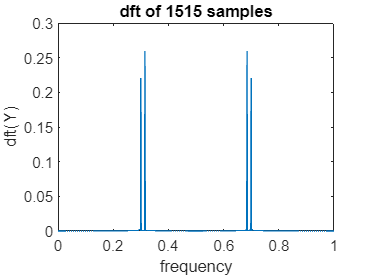

%Q3 for 1515 samples
figure;
N=1515;
n=0:N-1;
a=transpose(hamming(N));
y=(sin(120*pi/200.*n)+cos(126*pi/200.*n));
freq=(0:N-1)/N;
plot(freq,abs(fft(a.*y)/N))
title("dft of 1515 samples")
xlabel("frequency")
ylabel("dft(Y)")

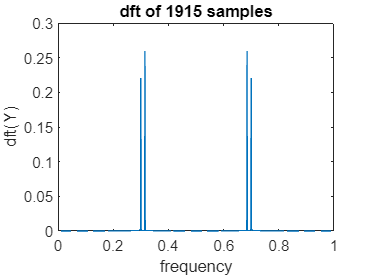

%Q3 for 1915 samples
figure;
N=1915;
n=0:N-1;
a=transpose(hamming(N));
y=(sin(120*pi/200.*n)+cos(126*pi/200.*n));
freq=(0:N-1)/N;
plot(freq,abs(fft(a.*y)/N))
title("dft of 1915 samples")
xlabel("frequency")
ylabel("dft(Y)")

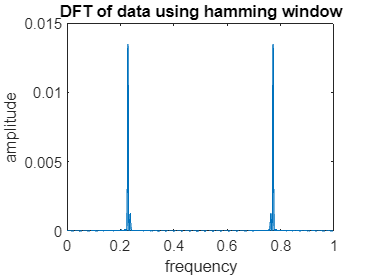

%
a=load('Exp4Data1.txt');
b=transpose(hamming(500));
C=(a.*b);
Fs=1;
N=10000;
fft_data=fft(C,N);
freq=(0:N-1)/N;
plot(freq,abs(fft_data)/N)

title("DFT of data using hamming window")
xlabel("frequency")
ylabel("amplitude")

[~, max_indices] = maxk(abs(fft_data), 2);
frequencies = freq(max_indices)*N;
disp(['Estimated Frequencies using Hamming Window: ', num2str(sort(frequencies))]);

Estimated Frequencies using Hamming Window: 2281  7719


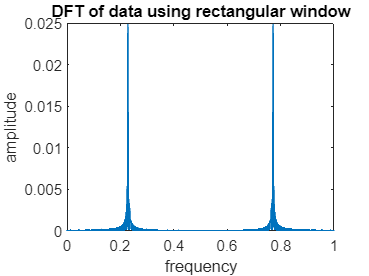

d=transpose(rectwin(500));
e=(a.*d);
Fs=1;
N=10000;
fft_data=fft(e,N);
freq=(0:N-1)/N;
plot(freq,abs(fft_data)/N)

title("DFT of data using rectangular window")
xlabel("frequency")
ylabel("amplitude")

[~, max_indices] = maxk(abs(fft_data), 2);
frequencies = freq(max_indices)*N;
disp(['Estimated Frequencies using Rectangular Window: ', num2str(sort(frequencies))]);

Estimated Frequencies using Rectangular Window: 2281  7719
